# Orbital Understanding Tool

## Patrick Williams

Autonomous Physics Group - Oklahoma State University

11/6/2023

c.G = 6.6743E-11; %Graviatational Constant (m^3 kg^-1 s^-2)
c.M_E = 5.97219E24 ;% mass of Earth, (kg)
c.R_E = 6378 ; %Radius of Earth, (km)

c.mu = c.G*c.M_E;

c.fd_1 = 0; %Distrubances on M1
c.fd_2 = 0; %Disturbances on M2

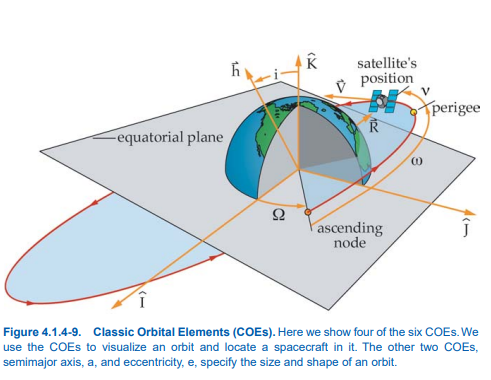

ISS Orbital Elements


$$\textrm{OE}=\left\lbrack a\;\left(\textrm{km}\right),e\;\left(-\right),i\;\left(\deg \right),\Omega \;\left(\deg \right),\omega \;\left(\deg \right),M\;\left(\deg \right)\right\rbrack$$



$${\textrm{OE}}_{\textrm{ISS}} =\left\lbrack 6800\;,0,\;52\ldotp 6^{\circ } ,\;121\ldotp 7^{\circ \;} ,\;197\ldotp 9^{\circ } ,279\ldotp 8^{\circ \;} \right\rbrack$$


a = 6796.179;           %Semi-Major axis, (km)
e = 0;                  %eccentricty, 0<= e < 1, (-)
i = 51.6;               %Inclination (deg)
RAAN = 121.65;          %Right Ascending Node, (deg), typically denoted by OMEGA
omega = 197.9818;       %Argument of Periaphis, (deg)
E = 279.8290;           %Mean Anomaly, (deg)

a2 = 10796.179;         %Semi-Major axis, (km)
e2 = 0.1;               %eccentricty, 0<= e < 1, (-)
i2 = 0;                 %Inclination (deg)
RAAN2 = 121.65;         %Right Ascending Node, (deg), typically denoted by OMEGA
omega2 = 197.9818;      %Argument of Periaphis, (deg)
E2 = 279.8290;          %Mean Anomaly, (deg)

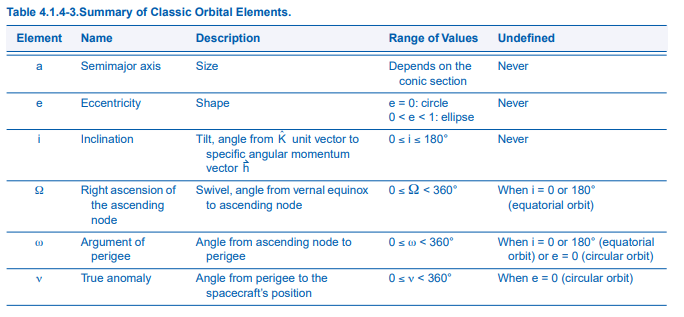

From [FAA manuvering In Space](https://www.faa.gov/sites/faa.gov/files/about/office_org/headquarters_offices/avs/III.4.1.4_Describing_Orbits.pdf)

OE = [a,e,i,RAAN,omega,E];
OE2 = [a2,e2,i2,RAAN2,omega2,E2];


%Calculate the Initial Conditions (x0,y0,z0,u0,v0,w0)
%and orbital period

Orbital Period


$$T=2\pi \;\sqrt{\frac{a^3 }{\mu \;}}$$


Initial Conditions


$$\begin{array}{l}
v=\textrm{true}\;\textrm{anomaly}\\
v=2\;\tan^{-1} \left(\sqrt{\;\frac{1+e}{1-e}}\tan \left(\frac{E}{2}\right)\right),e=\textrm{eccentricity},E=\textrm{Eccentric}\;\textrm{Anomaly}\;\left(\textrm{See}\;\textrm{SolveKepler}\ldotp m\right)
\end{array}$$


$x_0 =\frac{r_p \;\cos \left(v\right)}{1+e\;\cos \left(v\right)}$, $y_0 =\frac{r_p \;\sin \left(v\right)}{1+e\;\cos \left(v\right)}$, $z_0 =0$

$u_0 =-\sqrt{\frac{\mu \;}{r_p }}\sin \left(v\right)$, $v_0 =\sqrt{\;\frac{\mu }{r_p }}\left(e+\cos \left(v\right)\right)$, $w_0 =0$

3-1-3 Rotation


$$\textrm{Rot}=\left\lbrack \begin{array}{ccc}
\cos \left(\Omega \right)\cos \left(\omega \right)-\sin \left(\Omega \;\right)\sin \left(\omega \;\right)\cos \left(i\right) & -\cos \left(\Omega \;\right)\sin \left(\omega \right)-\sin \left(\Omega \right)\cos \left(\omega \right)\cos \left(i\right) & \sin \left(\Omega \right)\sin \left(i\right)\\
\sin \left(\Omega \right)\cos \left(\omega \right)+\cos \left(\Omega \right)\sin \left(\omega \right)\cos \left(i\right) & -\sin \left(\Omega \right)\sin \left(\omega \right)+\cos \left(\Omega \right)\cos \left(\omega \right)*\cos \left(i\right) & -1\cos \left(\Omega \right)\sin \left(i\right)\\
\sin \left(\omega \right)\sin \left(i\right) & \cos \left(\omega \right)\sin \left(i\right) & \cos \left(i\right)
\end{array}\right\rbrack$$



$$X_0 =\textrm{Rot}*\left\lbrack \begin{array}{c}
x_0 \\
y_0 \\
z_0 
\end{array}\right\rbrack ,V_0 =\textrm{Rot}*\left\lbrack \begin{array}{c}
u_0 \\
v_0 \\
w_0 
\end{array}\right\rbrack$$


see Sat_X0.m for more details


[TSat, SAT_X0] = Sat_X0(OE, c);
[TSat2, SAT_X2] = Sat_X0(OE2, c);

n = 3; %Number of Orbits for SAT1

%Runge-Kutta ODE45 Simulation


$$\ddot{\;\hat{\;r_{\textrm{sat}} } } =\frac{-\mu \;}{{r_{\textrm{sat}} }^3 }\hat{r_{\textrm{sat}} } +f_d ,\;\;\;\;\;\;\;\;\;\mu =G\left(M_{\textrm{Earth}} +M_{\textrm{sat}} \right),\;\;\;\;\;\;\;\textrm{note}\;M_{\textrm{sat}\;} \approx 0$$


See dynamics.m for more details

[TT, X] = ode45(@(t, X0) dynamics(t, X0, c), 0:1:TSat*n, SAT_X0);
%If you want to sim and plot additional orbits copy the following code and
%replace N with #

XX = X/1000; %Converts Values from m to km and m/s to km/s

%Note do not replace TSAT in the tspan slot, if you do you cannot directly
%compare the two orbits without interpolation!

%[TN, XN] = ode45(@(t, X0) dynamics(t, X0, c), 0:1:TSat, SAT_XN);
[T2, X2] = ode45(@(t, X0) dynamics(t, X0, c), 0:1:TSat*n, SAT_X2);


XX2 = X2/1000; %Converts Values from m to km and m/s to km/s


## Plotting

 figure
 s1 = plot(TT, sqrt(XX(:,1).^2 + XX(:,2).^2 + XX(:,3).^2) - c.R_E, 'r-')

s1 =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 … ]
              YData: [418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 … ]

  Show all properties

 hold on
 s2 = plot(T2, sqrt(XX2(:,1).^2 + XX2(:,2).^2 + XX2(:,3).^2) - c.R_E, 'b-')

s2 =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 … ]
              YData: [4.3407e+03 4.3401e+03 4.3395e+03 4.3389e+03 4.3383e+03 4.3377e+03 4.3371e+03 4.3364e+03 4.3358e+03 4.3352e+03 4.3346e+03 4.3340e+03 4.3334e+03 4.3328e+03 4.3322e+03 4.3316e+03 4.3310e+03 4.3303e+03 4.3297e+03 4.3291e+03 … ]

  Show all properties


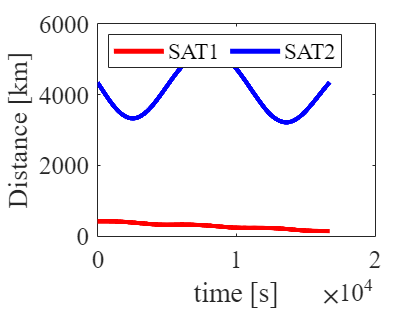


legend({'SAT1', 'SAT2'},...    
     'Location','northwest','NumColumns',3);
 set(gca,'Fontsize',20,'FontName','Times New Roman')
 xlabel('time [s]')
 ylabel('Distance [km]')
 set(s1, 'linewidth', 3.0)
 set(s2, 'linewidth', 3.0);

set(gca,'Fontsize',15,'FontName','Times New Roman');
hold off

% 
figure
s1 = plot(TT, sqrt(XX(:,4).^2 + XX(:,5).^2 + XX(:,6).^2), 'r-')

s1 =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 … ]
              YData: [7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 7.6584 … ]

  Show all properties


hold on
s2 = plot(T2, sqrt(XX2(:,4).^2 + XX2(:,5).^2 + XX2(:,6).^2))

s2 =   Line with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 … ]
              YData: [6.1200 6.1203 6.1207 6.1210 6.1214 6.1217 6.1221 6.1224 6.1228 6.1231 6.1234 6.1238 6.1241 6.1245 6.1248 6.1252 6.1255 6.1259 6.1262 6.1266 6.1269 6.1273 6.1276 6.1280 6.1283 6.1286 6.1290 6.1293 6.1297 6.1300 6.1304 6.1307 … ]

  Show all 

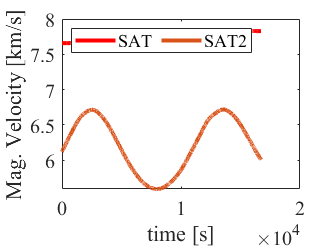



legend({'SAT', 'SAT2'},...    
    'Location','northwest','NumColumns',3);
set(gca,'Fontsize',20,'FontName','Times New Roman')
xlabel('time [s]')
ylabel('Mag. Velocity [km/s]')
set(s1, 'linewidth', 3.0)
set(s2, 'linewidth', 3.0);

set(gca,'Fontsize',15,'FontName','Times New Roman');
hold off


figure
w = sqrt(XX(:,1).^2 + XX(:,2).^2 + XX(:,3).^2);

w1 = plot(TT, sqrt((XX(:,1 )).^2 + (XX(:,2 )).^2 + (XX(:,3 )).^2) - c.R_E, '-r')

w1 =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 … ]
              YData: [418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 418.1790 … ]

  Show all properties

hold on
w2 = plot(T2, sqrt((XX2(:,1 )).^2 + (XX2(:,2 )).^2 + (XX2(:,3 )).^2)-c.R_E)

w2 =   Line with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 … ]
              YData: [4.3407e+03 4.3401e+03 4.3395e+03 4.3389e+03 4.3383e+03 4.3377e+03 4.3371e+03 4.3364e+03 4.3358e+03 4.3352e+03 4.3346e+03 4.3340e+03 4.3334e+03 4.3328e+03 4.3322e+03 4.3316e+03 4.3310e+03 4.3303e+03 4.3297e+03 4.3291e+03 … ]

  Show all prop



legend({'SAT', '12 km', '14 km'},...    
    'Location','northwest','NumColumns',3);

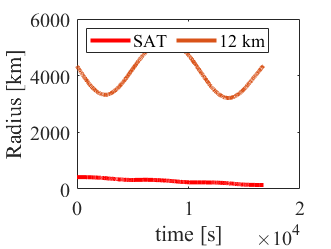

set(gca,'Fontsize',20,'FontName','Times New Roman');

xlabel('time [s]')
ylabel('Radius [km]')
set(w1, 'linewidth', 3.0);
set(w2, 'linewidth', 3.0);


set(gca,'Fontsize',15,'FontName','Times New Roman');
radd = sqrt((XX(:,1 )).^2 + (XX(:,2 ) - 0).^2) - c.R_E;% + (XX(:,3 ) - 0).^2)./1-0000;
%disp(radd)
hold off


figure
plot(XX(:,1),XX(:,2),'--r')
hold on
plot(XX2(:,1),XX2(:,2), '--b')
%plotcircle(0,0,c.R_E, '-k')
viscircles([0,0],c.R_E)

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


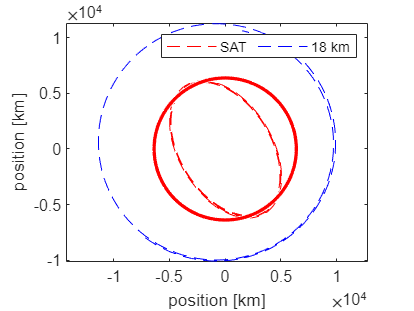


xlabel('position [km]')
ylabel('position [km]')
axis('equal')

legend({'SAT', '18 km'},...
    'Location','northeast','NumColumns',2);
hold off

## Plotting (3D)

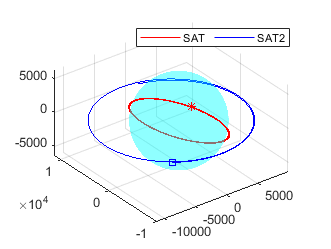

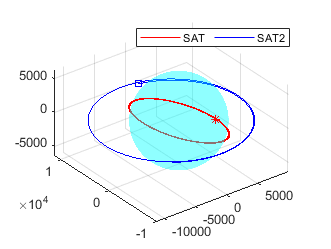

figure
[sx,sy,sz] = sphere(100); %Do not Change

%Adjust Axis as needed.
xl = [-10000, 10000] ; yl = [-10000, 10000] ; zl = [-10000, 10000] ;

axis equal
for i = 1:100:size(XX,1)

    % Orbits
    plot3(XX(:,1),XX(:,2),XX(:,3),'-r');
    hold on;
    plot3(XX2(:,1),XX2(:,2),XX2(:,3),'-b');

    surf(c.R_E*sx,c.R_E*sy,c.R_E*sz,'FaceAlpha',0.25,'EdgeColor','none', 'FaceColor','c')
    
    % Satellites 
    plot3(XX(i,1),XX(i,2),XX(i,3),Marker="*",Color='red' );
    plot3(XX2(i,1),XX2(i,2),XX2(i,3),Marker="square",Color='blue');


    axis ([xl yl zl])
    drawnow
    axis equal
    grid on
    legend({'SAT', 'SAT2'},...
    'Location','northeast','NumColumns',2);
    hold off;
end

## LAT LONG PLOTS

lat_sat = rad2deg(asin(XX(:,3)./(sqrt(XX(:,1).^2+XX(:,2).^2+XX(:,3).^2))))+0;
long_sat = rad2deg(atan2(XX(:,2),XX(:,1)));
lat2 = rad2deg(asin(XX2(:,3)./(sqrt(XX2(:,1).^2+XX2(:,2).^2+XX2(:,3).^2))))+0;
long2 = rad2deg(atan2(XX2(:,2),XX2(:,1)));

figure

    h = geoshow('landareas.shp')

h =   Group with properties:

    Children: [537×1 Patch]
     Visible: on
     HitTest: on

  Show all properties


    hold on
    h2 = geoshow(lat_sat, long_sat)

h2 =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-108.0120 -107.9348 -107.8577 -107.7807 -107.7039 -107.6270 -107.5503 -107.4737 -107.3971 -107.3206 -107.2442 -107.1679 -107.0917 -107.0156 -106.9395 -106.8635 -106.7876 -106.7118 -106.6361 -106.5605 -106.4849 -106.4095 … ]
              YData: [43.8817 43.8489 43.8161 43.7832 43.7503 43.7173 43.6842 43.6511 43.6180 43.5848 43.5516 43.5183 43.4849 43.4516 43.4181 43.3846 43.3511 43.3175 43.2838 43.2501 43.2164 43.1826 43.1488 43.1149 43.0809 43.0469 43.0129 42.9788 … ]
              ZData: [1×0 double]

  Show all 

    h3 = geoshow(lat2, long2)

h3 =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-131.9990 -131.9665 -131.9339 -131.9014 -131.8688 -131.8362 -131.8037 -131.7711 -131.7385 -131.7059 -131.6734 -131.6408 -131.6082 -131.5756 -131.5430 -131.5104 -131.4778 -131.4451 -131.4125 -131.3799 -131.3473 -131.3147 … ]
              YData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 … ]
              ZData: [1×0 double]

  Show 

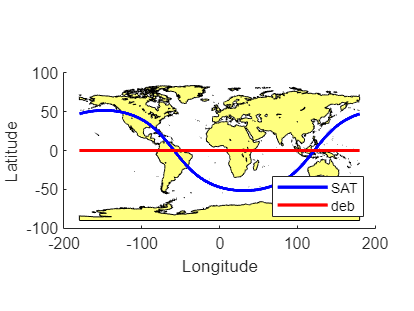

    
    %hold on
    xlabel('Longitude')
    ylabel('Latitude')

    set(h2, 'linewidth', 2.0);
    set(h3, 'linewidth', 2.0,'Color','red');
    
    legend({'SAT', 'deb'},...
    'Location','southeast','NumColumns',1);

    hold off


    %ITEM = sqrt((X2(:,1)-XX(:,1)).^2 + (X2(:,2)-XX(:,2)).^2 + (X2(:,3)-XX(:,3)).^2);
    %u = min(ITEM)
